# MATLAB Testing Strategies

### Load Data

Load data from a binary file. The data includes 100 datasets of entries and exits in the datetime format.

clear
load timestampsCN.mat entryTimestamps exitTimestamps

### Process Data

First, we may want to calculate the duration between entry and exit for each data set. It is interesting to calculate the number of durations and the mean duration.

durations = exitTimestamps-entryTimestamps;
numberOfDurations = numel(durations);
averageDuration = mean(durations)

averageDuration = duration
   04:12:35


### Visualize Data

We visualize the duratons in a simple plot including the mean value as a horizontal line for reference.

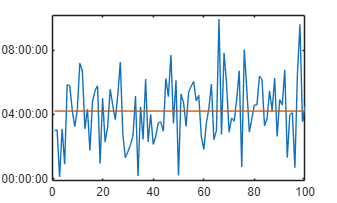

figure, plot(durations)
hold on
plot([1,numberOfDurations],[averageDuration, averageDuration])
hold off

### Check Short Durations

Find short durations with the help of a function and calculate the amount.

numberOfShortDurations=getShortDurations(durations,hours(inf));
numberOfShortDurations/numberOfDurations

ans = 1


expextedNumberOfDurations=length(durations)

expextedNumberOfDurations = 100


assert(actualNumberOfDurations==expectedNumberOfDurations)

Unrecognized function or variable 'actualNumberOfDurations'.